•Plotar as curvas características do dutycicleD em função de Io/Io,max.

•Valores de Vo/E: 0.2, 0.5 e 0.8.

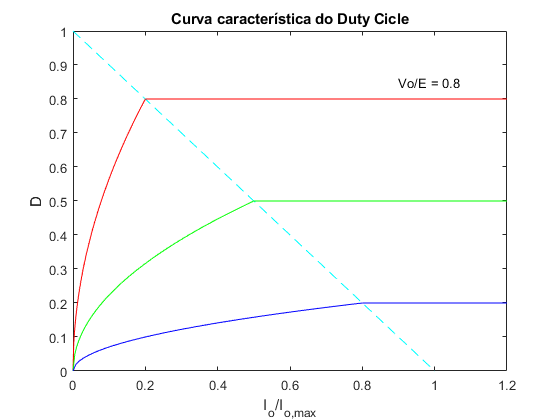

% Fronteira
% m = Vo/E
% n = Io/Io,max

n = linspace(0,1,100);
D = 1 - n;
plot(n,D,'c--'); hold on;

% Descontínua
n = linspace(0,0.2,100);
m = 0.8;
D = m*sqrt(n/(1-m));
plot(n,D,'r'); hold on;

n = linspace(0,0.5,100);
m = 0.5;
D = m*sqrt(n/(1-m));
plot(n,D,'g'); hold on;

n = linspace(0,0.8,100);
m = 0.2;
D = m*sqrt(n/(1-m));
plot(n,D,'b'); hold on;

% Contínuo
n = linspace(0.2,1.2,100);
for i = 1:100
   m(i) = 0.8;
   D(i) = m(i);
end
plot(n,D,'r'); hold on;

n = linspace(0.5,1.2,100);
for i = 1:100
   m(i) = 0.5;
   D(i) = m(i);
end
plot(n,D,'g'); hold on;

n = linspace(0.8,1.2,100);
for i = 1:100
   m(i) = 0.2;
   D(i) = m(i);
end
plot(n,D,'b'); hold on;

title('Curva característica do Duty Cicle Buck');
xlabel('I_{o}/I_{o,max}');
ylabel('D');
text(0.9,0.85,'Vo/E = 0.8')